
filePath = 'E:/iith/sem7/BM4081/frames/1/frame-dicom-00001.dcm';


dicomInfo = dicominfo(filePath);
originalImage = dicomread(dicomInfo);

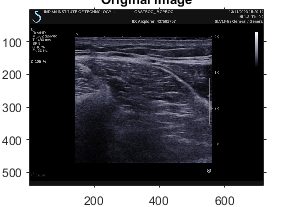


figure;
imshow(originalImage, []);
title('Original Image');


originalImage=rgb2gray(originalImage);

preprocessedImage = medfilt2(originalImage);

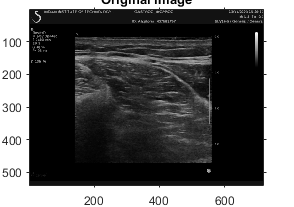

figure;
imshow(preprocessedImage, []);
title('Original Image');

enhancedImage = imadjust(preprocessedImage,[],[],2);

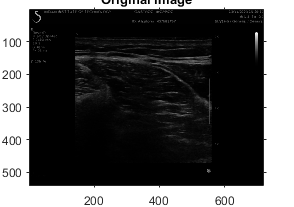

figure;
imshow(enhancedImage, []);
title('Original Image');

radius = 2;
se = strel('disk',radius);

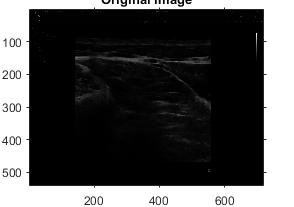

segImage=imerode(enhancedImage,se);
figure;
imshow(segImage, []);
title('Original Image');

len = 2;
se=strel('line',len,90)

se = strel is a line shaped structuring element with properties:

      Neighborhood: [3×1 logical]
    Dimensionality: 2


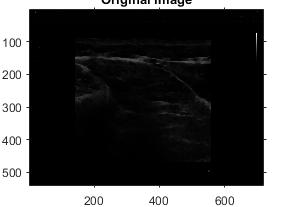

segImage2=imerode(segImage,se);
figure;
imshow(segImage2, []);
title('Original Image');

img = imcrop(segImage2,[160.5 123.5 378 80]);
imwrite(img,'E:/iith/sem7/BM4081/croppedFrames/1/cropped1.png')